## TOPIC 6: Building solutions to problems, part 1

ENGR105, 9/22/20

#### Recap of topics covered so far:

- MATLAB syntax and basics: using MATLAB to perform calculations

- Scalars, vectors, and matrices: storing, accessing, and manipulating numerical information

- Functions and scripts: creating useful collections of code

- `for` and `while` loops: creating code that efficiently repeats tasks

- Conditionals: incorporating decision making into your code

**1) MATLAB syntax and basics: using MATLAB to perform calculations**

We've learned how to use MATLAB as a tool for performing simple mathematical calculations.

% Using comments to explain our code, we can perform basics tasks, look up
% information about functions, etc.
1 + 2

ans = 3

% We have learned how to use the resources in MATLAB to perform basic
% calculations
5*tan(pi/4)

ans = 5.0000

a = 15; % Assigning a scalar variable
b = 13+2/a;  % Creating a statement based on the previous variable
disp(b) % Display the newly defined variable

   13.1333



**2) Scalars, vectors, and matrices: storing, accessing, and manipulating numerical information**

MATLAB excels with and is optimized for performing operations on vector, matrices, and higher order arrays. We have learned how to create vector, matrices, etc., access their components through indexing, and perform array mathematics. This is the basis for **vectorization** of solutions.

% Create vectors
a = 1:5;
b = linspace(1,4,5);
c = zeros(3,3);
c(1:9) = randi(5,[1,9]);
disp(a)

     1     2     3     4     5



disp(b)

    1.0000    1.7500    2.5000    3.2500    4.0000



disp(c)

     1     5     2
     3     2     3
     2     2     1



% Access elements in the vectors and matrix
a([1:2,end])

ans =      1     2     5


b(randi(5,[1,10]))

ans =     2.5000    2.5000    3.2500    1.0000    3.2500    1.0000    4.0000    2.5000    2.5000    1.0000


c([1,3],[1,3])

ans =      1     2
     2     1


% Perform array math
a+b     % vector addition

ans =     2.0000    3.7500    5.5000    7.2500    9.0000


a.*b    % element-wise multiplication

ans =     1.0000    3.5000    7.5000   13.0000   20.0000


(a')*b  % matrix multiplication

ans =     1.0000    1.7500    2.5000    3.2500    4.0000
    2.0000    3.5000    5.0000    6.5000    8.0000
    3.0000    5.2500    7.5000    9.7500   12.0000
    4.0000    7.0000   10.0000   13.0000   16.0000
    5.0000    8.7500   12.5000   16.2500   20.0000


a(1:3)+c(1,:)   % Adding subvectors derived from original array

ans =      2     7     5


**3) Functions and scripts: creating useful collections of code**

We have created assemblages of code to run a series of tasks. Scripts are simply collections of multi-line code. Functions perform collections of code, take inputs, and return outputs to the base MATLAB workspace.

An example function declaration:

This example function takes **three** inputs and returns **two** outputs.

**4) **`for`** and **`while`** loops: creating code that efficiently repeats tasks**

- `for` loops are useful when one knows (or can calculate) the number of iterations to perform ahead of time. 

a = zeros(1,10);    % Preallocate vector to store values
% Perform 10 iterations, each iteration calculate square root of different
% random number
for k = 1:10
    a(k) = sqrt(randi(k));
end
disp(a)

    1.0000    1.0000    1.0000    2.0000    1.0000    1.0000    1.4142    2.0000    2.4495    2.8284



- `while` loops are useful when one does not know how many iterations must be performed.

% Create a vector containing all multiples of 13 less than 300;
a = 13; % vector to store integer multiples of 13. Start by populating first (obvious) case
num = 1;    % counter to determine next multiple
while a(end) < 300
    num = num + 1;
    a(end+1) = num*13;
end
a(end) = [];    % Delete the last entry because it will be over 200;
disp(a)

    13    26    39    52    65    78    91   104   117   130   143   156   169   182   195   208   221   234   247   260   273   286   299



**5) Conditionals: incorporating decision making into your code**

Like `while` loops, conditionals use **logical and relational operators** to determine which piece of conditional code will be executed. This provides instructions that enables your code to *decide* how to proceed.

% Generate two random numbers
a = randi(5);
b = randi(5);

if a==b % if variables are equal
    disp(a*b*ones(1,a*b))
elseif a<b % if b is greater than a
    disp(b*ones(1,a))
else    % if a is greater than b
    disp(a*ones(1,b))
end

     3



### Using scientific computing to approach problems

The above syntax and programming capabilities are tools for solving scientific problems. We are ultimately interest in applying these tools (and other syntax, computational capabilities, and programming concepts) to solve problems. 

**NOTE**: developing a solution to a problem often seems **daunting** at first. As you are getting started with scientific computing, approach new problems in a **systematic** way, breaking the overall task into simpler sub-tasks. One systematic approach is discussed here.

#### PRO: a roadmap for building computational solutions

**1) ****P**lan, **P**repare, and **P**seudocode

The first thing to do, before writing any code, is to develop a plan breaking down the steps that your code should accomplish to produce the desired solution. 

- Identify the problem being solved and propose the type of computational solution necessary.

- Identify what is known, what should be calculated, and what is to be solved for or output. Write out equations and draw pictures by hand.

- While you may start by writing or sketching this on paper (I do this), convert your handwritten notes and thoughts into **MATLAB comments**.

- Lay out your comments spatially in a script (.m) file or Livescript code. The spatial layout of your comments should indicate the **order of tasks** you want to perform.

- Your comments should be **pseudocode**: they should be written in English and convey what you want your code to accomplish.

*****  Your pseudocode is the foundation for your solution *****

**2)** w**R**ite **R**ough (increments of code) and **R**efine 

The second thing to do, once you have produced pseudocode, is to start filling in sections of code *in increments*, with rough code that simply works. That is, build your computational 

- Do **NOT** try to "hit a home run" on your first attempt by generating perfect code immediately.

- Systematically fill in pieces of code, ensure that they run properly and as expected.

- Start with rough (potentially inefficient) code that simply produces the correct output.

- Deal with errors and malfunctions as necessary.

- Use your rough code in one section to start the next section.

- Consistently refine your code throughout this process.

- If your ultimate goal is to produce a complex piece of code involving functions, start by writing all functions as scripts to ensure that each function performs as you expect

***** Your rough code, built upon the pseudocode foundation, is the "core structure" and "meat" of your solution *****

**3) ****O**ptimize and improve

The final thing to do is to convert your rough code into an optimal solution.

- Ensure that all functions are packaged properly and clear.

- Ensure your code is clear and well-commented.

- Ensure your code is operating as computationally efficient as possible. Look for ways to increase performance (e.g. vectorization vs. for loops, preallocation, etc.)

***** Your optimized solution "polishes" the code structure and foundation you have built *****

#### Troubleshooting and debugging techniques

When you start developing a computational solution to a problem, expect errors and issues to arise. Anticipating potential errors will help you more quickly overcome them and produce working code. 

***Potential errors and issues include:***

***1) Your code does not run***

*Debugging techniques and tips:*

- The issue is most likely either MATLAB syntax or a function being used improperly.

- Use the error information to identify where in your code the issue is happening.

- Unsuppress outputs (remove `;`) to print the results of computations to the command line.

- Insert a **breakpoint** to step through a script or function. Compare the computations to what you expect.

- If you are making a function, start by creating it as a script. Once that runs properly, expand that code into a function.

- Use `disp()` to output a variable to the command line.

- Run sections of code at a time to observe how the expect outputs change through the script.

- Comment large sections of code to isolate where the error is occuring.

*Example:*

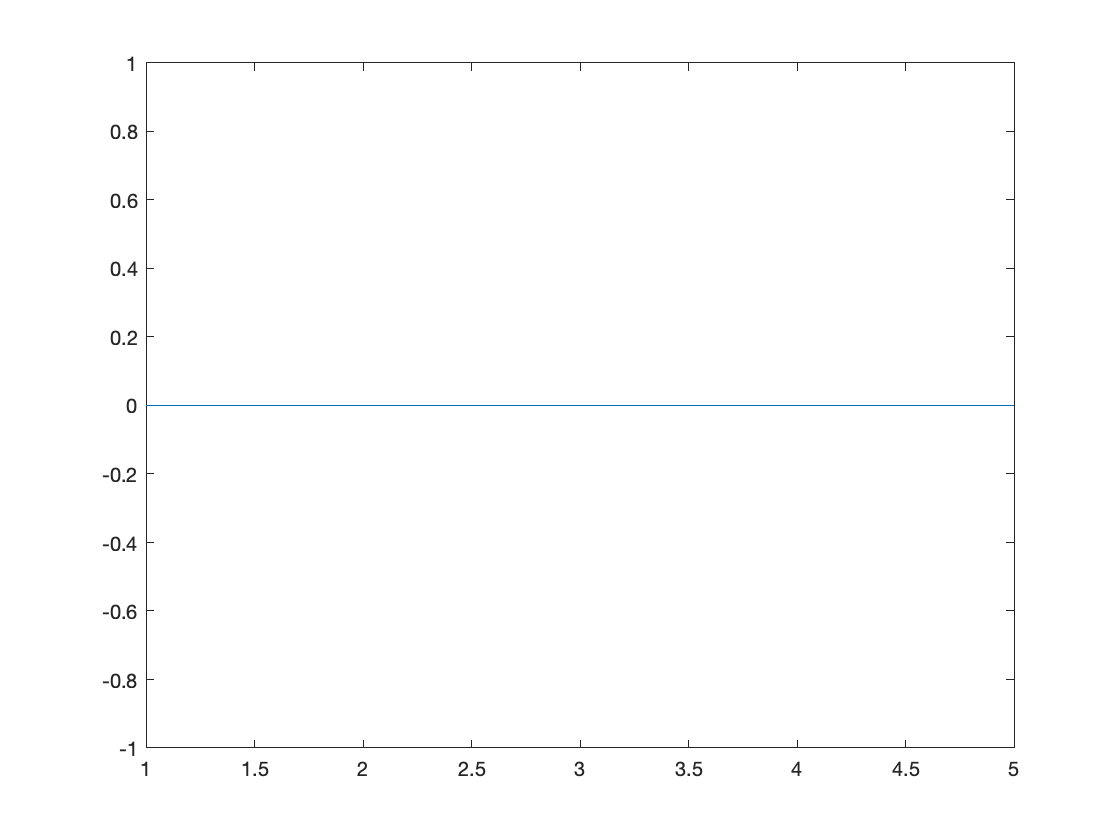

a = [5,2,1];
b = zeros(3,1);

% Goal: produce a plot
plot(a,b)

***2) Your code runs but the output is not in the correct form***

*Debugging techniques and tips:*

- The issue is most likely MATLAB syntax -- you might be using a function incorrectly, incorrectly produced an array of the wrong size, etc.

- Compare the output from your code at various points to determine where values deviate from what is expected.

- Unsuppress outputs (remove `;`) or use `disp()` to print the results of computations to the command line.

- Insert a **breakpoint** to step through a script or function. Compare the computations to what you expect.

*Example:*

% Goal: create  matrix through matrix multiplication
a = 1:5;
b = ones(5,1);
a*b

ans = 15

***3) Your code runs and produces the correct form of output, but it is not physical or realistic***

*Debugging techniques and tips:*

- As above, the issue is most likely MATLAB syntax -- you might have mis-entered an equation, misused an operator, etc.

- Compare the output from your code at various points to determine where values deviate from what is expected.

- Unsuppress outputs (remove `;`) or use `disp()` to print the results of computations to the command line.

- Insert a **breakpoint** to step through a script or function. Compare the computations to what you expect.

*Example:*

% % Goal: calculate the terminal velocity of a falling object (positive is
% % down)
g = 9.81; % m/s^2
d = 0.001; % diameter, m
mu = 10^-3; % Pa*s
pm = 1000; % kg/m^3
ps = 1050; % kg/m^3

Vt = g*d^2/(12*mu)*(ps - pm)

Vt = 0.0409

#### Getting started with building computational solutions to problems.

We will practice applying what we have learned to four different example problems representing a few different applications of scientific computing.

- Modeling the motion of a projectile

- Creating a numerical method to find the root of an equation

- Programming a gameplay algorithm 

### Practice problem 1: modeling the motion of a projectile 

In your introductory physics courses, you studied kinematics and the motion of projectiles. Such analyses may apply in many circumstances, including a system in which a ball is thrown at some angle relative to the ground, as seen below.

                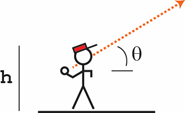

Consider a **2 m **tall athlete who can easily throw the ball **30 m/s**. Assume the ball is released at the top of the player's head. **Determine and plot the maximum height of the ball and the distance thrown (assuming the ball doesn't bounce) as a function of the angle by which the ball is thrown.**

**PRO, Step 1****: ****P**lan, **P**repare, and **P**seudocode

Helpful tasks:

- When faced with a problem, it is helpful to first take a step back, take a deep breath, and write down what we know. In this case, we know from a force balance on the ball immediately after it is thrown that the ball's acceleration, velocity, and position can be represented by the following equations (neglecting any air resistance):

                    
$$\begin{array}{l}
a_x \left(t\right)=\frac{d^2 x}{{\textrm{dt}}^2 }\;=\;0\\
a_y \left(t\right)=\frac{d^2 y}{{\textrm{dt}}^2 }\;=-g\\
v_x \left(t\right)=\;\frac{\textrm{dx}}{\textrm{dt}}\;=v_0 \;\cos \left(\theta \right)\\
v_y \left(t\right)=\;\frac{\textrm{dy}}{\textrm{dt}}\;=v_0 \;\sin \left(\theta \right)-g\;t\\
\begin{array}{l}
x\left(t\right)=v_0 \;\cos \left(\theta \right)t\\
y\left(t\right)=h\;+\;v_0 \;\sin \left(\theta \right)t-\frac{g}{2}t^2 
\end{array}
\end{array}$$


- We know the equations describing our system. **How can we calculate the max height and distance thrown?**

**Distance thrown**. To calculate the distance the ball travels in the air. we first find the time at which the ball lands by setting `y(t)` to zero and solving for `t`.

            
$$\begin{array}{l}
0=h\;+\;v_0 \;\sin \left(\theta \right)t_{\textrm{end}} -\frac{g}{2}t_{\textrm{end}}^2 \\
t_{\textrm{end}} =\frac{-v_0 \;\sin \left(\theta \right)-\sqrt{v_0^2 \;\sin^2 \left(\theta \right)+2g\;h}}{-g}
\end{array}$$


The above is obtained simply by using the quadratic formula. Substituting `t_end` into `x(t)` produces the distance the ball travels.

            
$$x_{\textrm{end}} =v_0 \;\cos \left(\theta \right)t_{\textrm{end}}$$


**Maximum height**. To calculate the maximum height of the ball, calculate when the` y` component of the velocity (or the derivative of the `y` position) is zero, as this will be the peak of the trajectory.

            
$$\begin{array}{l}
v_y \left(t\right)=0\;=v_0 \;\sin \left(\theta \right)-g\;t_{\textrm{peak}} \\
t_{\textrm{peak}} =\frac{v_0 \;\sin \left(\theta \right)}{g}
\end{array}$$


Substituting into the equation for y(t), we determine the maximum height of the ball.

            
$$y_{\max } =h\;+\;v_0 \;\sin \left(\theta \right)t_{\textrm{peak}} -\frac{g}{2}{t_{\textrm{peak}} }^2$$


**Note**: *(as seen above)* before producing a computational solution, it is useful to set up the problem by writing out (by hand) all of the known variables and equations describing the system.

- What is the objective of our code? In this case, we want to calculate two values as a function of an input angle and then repeat that calculation for multiple input angles. Thus, you may envision eventually using **some iteration**.

- We now know all the equations that we need to solve this problem, but how is that converted into code? Write out the **pseudocode** for what the script may look like.

%step 1: specify angle


%step 2: constants

% Repeat for all angles 
%step 3: calculate distance for each theta

%step 4: calculate maximum height


**PRO, Step 2****: **w**R**ite **R**ough (increments of code) and **R**efine 

Helpful tasks:

- Starting with your pseudocode, roughly fill in code.

- While we eventually may want to use a loop, write out all the code as a script with one "test input."

% %step 1: specify angle
% th = 45; %in degrees
% th_r = th*pi/180;%radians
%
% %step 2: constants
% g = 9.81; %m/s^2
% h = 2; %height
% v0 = 30; %initial velocity
%
% %step 3: calculate distance for theta
% t_end = (-v0*sin(th_r) - sqrt(v0^2*sin(th_r)^2 + 2*g*h))/(-g);
% x_end = v0 *cos(th_r)*t_end
%
% %step 4: caculate max height
% t_peak = v0*sin(th_r)/g;
% y_peak = h + v0*sin(th_r)*t_peak - g/2*t_peak

%step 1: specify angle
th = 45; %in degrees
th_r = th*pi/180;%radians

%preallocationg 
x_end = zeros(1,length(th));
y_peak = zeros(1,length(th));

%step 2: constants
g = 9.81; %m/s^2
h = 2; %height
v0 = 30; %initial velocity

for k = 1:length(th)
    %step 3: calculate distance for theta
    t_end = (-v0*sin(th_r(k)) - sqrt(v0^2*sin(th_r(k))^2 + 2*g*h))/(-g);
    x_end(k) = v0 *cos(th_r(k))*t_end;
    
    %step 4: caculate max height
    t_peak = v0*sin(th_r(k))/g;
    y_peak(k) = h + v0*sin(th_r(k))*t_peak - g/2*t_peak^2;
end
plot(th,x_end,'k.')

**PRO, Step 3:** **O**ptimize and improve

There are a number of issues to optimize here:

- Constants are being defined inside the for loop

- For loops are generally more inefficent that vectorization

% %step 1: specify angle
th = 45; %in degrees
th_r = th*pi/180;%radians

% %step 2: constants
g = 9.81; %m/s^2
h = 2; %height
v0 = 30; %initial velocity
%
% %step 3: calculate distance for theta
t_end = (-v0*sin(th_r) - sqrt(v0^2*sin(th_r)^2 + 2*g*h))/(-g);
x_end = v0 *cos(th_r)*t_end

% %step 4: caculate max height
t_peak = v0*sin(th_r)/g;
y_peak = h + v0*sin(th_r)*t_peak - g/2*t_peak;
plot(th,x_end,'k-')

### Practice problem 2: numerical methods and root-finding

Numerical analysis is the domain of mathematics and computer science that creates, analyzes, and implements algorithms for solving numerically the problems of continuous mathematics. Numerically solving a complex math problem often involves iterating or following a given algorithm until it converges (hopefully) upon a solution, within some defined tolerance. 

One such application of numerical methods is root-finding, the algorithms for which may quickly find the root ($F\left(x\right)=0$) for some arbitrary function $F\left(x\right)$. Say we have a (potentially very nonlinear) function for which we want to find $F\left(x\right)=0$ quickly. The Newton-Raphson method searches for the root of a function by iteratively following where the tangent of a function crosses the `x` axis.  

Specifically,** the Newton-Raphson method has the following algorithm:**

- Pick an initial guess ($x_1$) of the root of a function.

- At that x value, calculate the tangent to the curve of the function.

- Find where the tangent to the curve intersects the x axis.This x value becomes $x_2$.

- At this new x value, repeat steps 2-3.

- When the new x value is not much different than the previous x value (as determined by some pre-defined tolerance), conclude that you have found an approximation for the root of the function. That is, you found a numerical approximation for the x value for which $F\left(x\right)=0$.

#### Visual depiction of the Newton-Raphson algorithm

**Iteration 1:** Make an initial guess, calculate where the tangent line at that point intersects x axis.

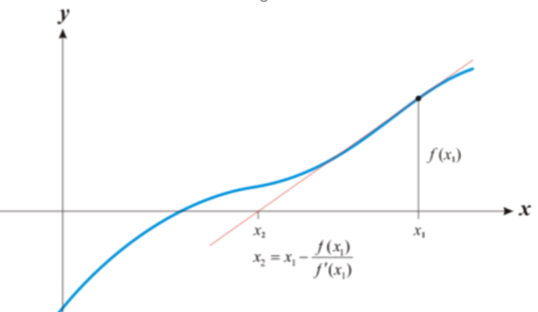

**Iteration 2:** Using this new x value, repeat the process

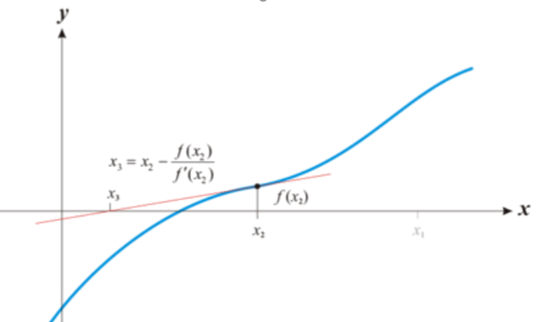

**Iteration 3:** The algorithm is beginning to converge on the root of $F\left(x\right)$.

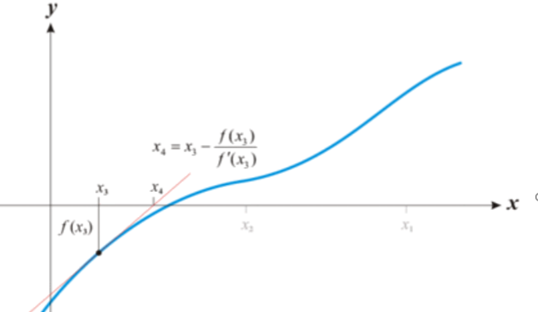

In these images, $x_n$ is the current guess for the root and $x_{n+1}$ is the next input in this iterative process. When $x_n$ -> $x_{n+1}$, we have found the root of the function.

#### Derivation of the Newton-Raphson method

1) The tangent line of the function at some point *x *can be written generally as:

                
$$y=m\;x+b$$


2) The slope, *m*, is simply the derivative of the function at `x``n:`

                
$$y=f^{\prime } \left(x_n \right)\;x+b$$


`3) `At *x *= `x``n`, y = *f(*`x``n`*)*, which allows us to solve for *b*

                
$$f\left(x_n \right)=f^{\prime } \left(x_n \right)x_n +b\longrightarrow b=f\left(x_n \right)-f^{\prime } \left(x_n \right)x_n$$


4) Substituting, we can write an equation for the tangent line in terms of $f\left(x_n \right)$,$f^{\prime } \left(x_n \right)$,$x_n$:

                
$$y=f^{\prime } \left(x_n \right)x+\left(f\left(x_n \right)-f^{\prime } \left(x_n \right)x_n \right)$$


5) In this algorithm, we solve for *y *= 0 for the tangent line. Thus, at y=0, and *x* = `x``n+1`:

                
$$0=f^{\prime } \left(x_n \right)x_{n+1} +\left(f\left(x_n \right)-f^{\prime } \left(x_n \right)x_n \right)$$


6) Rearranging the previous for `x``n+1` produces the Newton-Raphson equation:

                
$$x_{n+1} =x_n -\frac{f\left(x_n \right)}{f^{\prime } \left(x_n \right)}$$


**Thus, we have derived a numerical method for iterating until we converge on the root of a function.**

#### **Question 1**

**Use the Newton-raphson method to find the roots to the following equation:**

            
$$f\left(x\right)=x^4 +2{\left(x-2\right)}^2 -20$$


**PRO, Step 1****: ****P**lan, **P**repare, and **P**seudocode

Helpful tasks:

- We know the equation we want to solve for, can we plot it to get an idea of where the roots might be?

- We know the equation and the algorithm, can we write explicitly write out what the algorithm will look. That is, here:

            
$$\begin{array}{l}
f\left(x\right)=x^4 +2{\left(x-2\right)}^2 -20\\
f^{\prime } \left(x\right)={4x}^3 +4\left(x-2\right)
\end{array}$$


- We know the algorithm, but how is that converted into code? Write out pseudocode for what the script will look like.

% Step 1: specify 1 angle% 
% Step 2: constants% Repeat for all angles% 
% Step 3: calculate distance for each theta% 
% Step 4: calculate maximum height

**PRO, Step 2****: **w**R**ite **R**ough (increments of code) and **R**efine 

Helpful tasks:

- Starting with your pseudocode and what you know about the function, roughly fill in code.

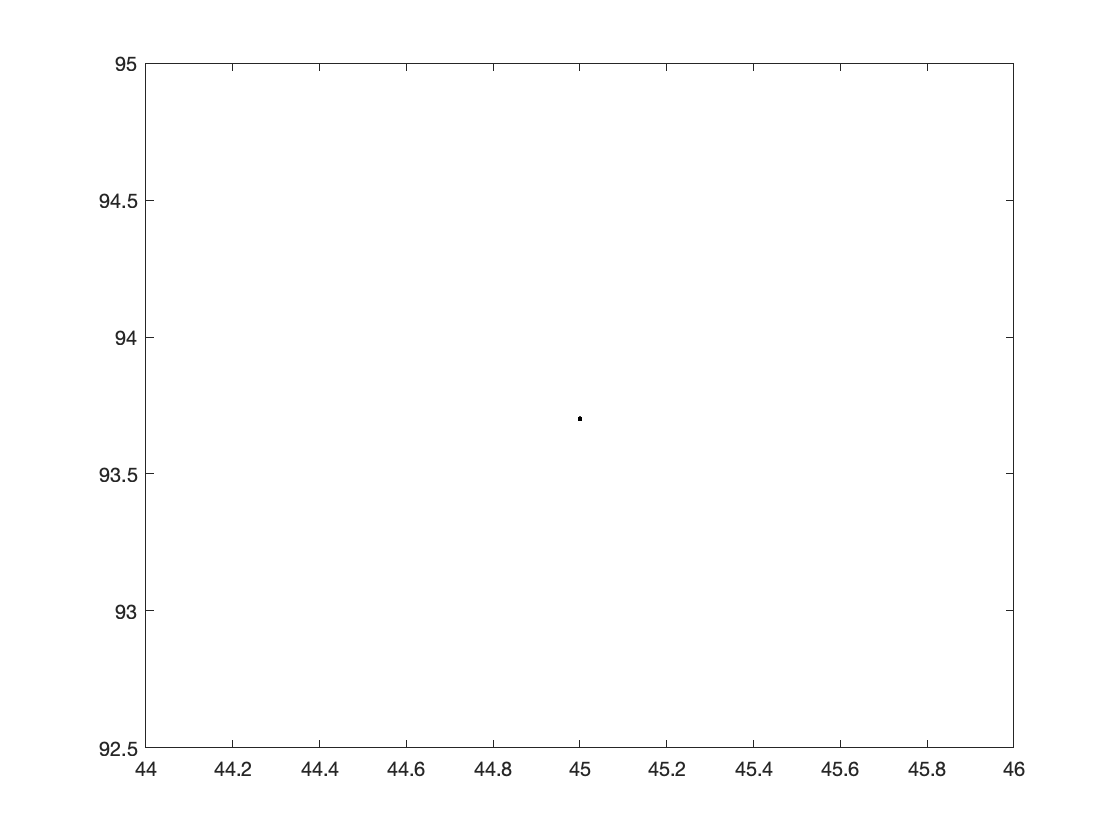

%Step 1: specify angle
th = 0:0.005:90; %degrees

th_r = th*pi/180; %radians

%Preallocate vector
x_end = zeros(1,length(th));
y_peak = zeros(1,length(th));

%Step 2: constants 
g = 9.81; %m/s^2
h = 2; %m
v0 = 30; %m/s

%repeat for each theta
for k = length(th)
    %repeat for all angles
    %step 3: calculate distance for each theta
    

x_end = 93.7013

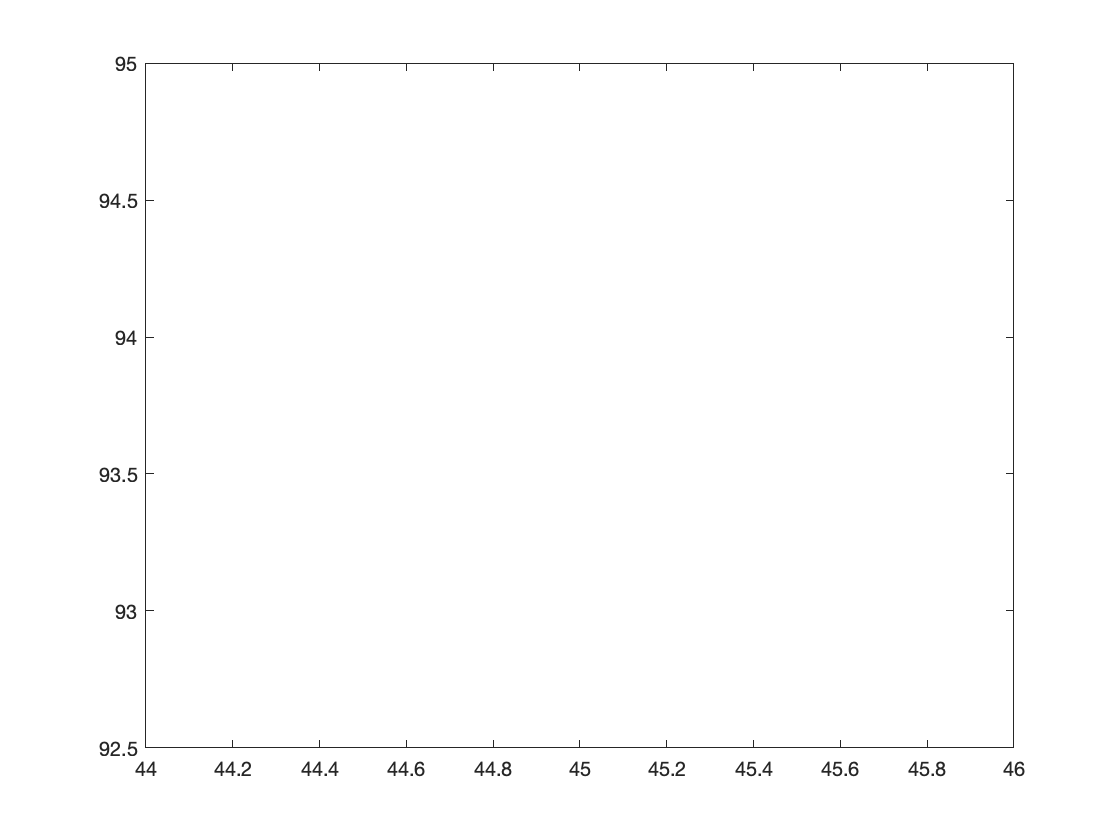

    t_end = (-v0*sin(th_r(k)) - sqrt(v0^2*sin(th_r(k))^2 + 2*g*h))/(-g);
    x_end(k) = v0*cos(th_r(k))*t_end;
    
    %Step 4L calculate maximum height 
    t_peak = v0*sin(th_r(k))/g;

    y_peak(k) = h + v0*sin(th_r(k))*t_peak - g/2*t_peak^2;
end

%plot the distance 
plot(th,x_end,'k.')

% Plot the height of the ball
plot(th,y_peak,'k.')




**PRO, Step 3:** **O**ptimize and improve

We don't actually know how many loop iterations to perform ahead of time. Refine the code so that it is in the form of a `while` loop.


%Step 1: specify angle
th = 0:0.005:90; %degrees
th_r = th*pi/180; %radians

%Preallocate vector
x_end = zeros(1,length(th));
y_peak = zeros(1,length(th));

%Step 2: constants 
g = 9.81; %m/s^2
h = 2; %m
v0 = 30; %m/s

% Step 3: Calculate distance thrown - element-wise
t_end = (-v0*sin(th_r) - sqrt(v0^2*sin(th_r).^2 + 2*g*h))/(-g);
x_end = v0*cos(th_r).*t_end;

% Step 4: calculate maximun height 
t_peak = v0*sin(th_r)/g;
y_peak = h + v0*sin(th_r).*t_peak - g/2*t_peak.^2;

%plot the distance 
plot(th,x_end,'k.')
xlabel('Angle thrown (degrees)')
ylabel('Distance thrown (m)')


% Plot the height of the ball
plot(th,y_peak,'k.')
xlabel('Angle thrown (degrees)')
ylabel('Heigth thrown (m)')

Note: this example has two roots. The root to which the function converges is dependent on the initial guess of the root location

#### **Question 2**

**Use the Newton-raphson method to create a function for numerically approximating the square root of any number.**

**PRO, Step 1****: ****P**lan, **P**repare, and **P**seudocode

Helpful tasks:

- We know the equation we want to solve for, let's convert it into a form that is easily used with Newton-raphson

            
$$\begin{array}{l}
x=\sqrt{a}\\
x^2 =a\\
0=x^2 -a
\end{array}$$


            In other words, we want to find the root for the following equation:

            
$$f\left(x\right)=x^2 -a$$


- We know the equation and the algorithm, can we write explicitly write out what the algorithm will look. That is, here:

            
$$\begin{array}{l}
f\left(x\right)=x^2 -a\\
f^{\prime } \left(x\right)=2x
\end{array}$$


            
$$x_{n+1} =x_n -\frac{f\left(x_n \right)}{f^{\prime } \left(x_n \right)}$$


- We know the algorithm, but how is that converted into code? Write out pseudocode for what the script will look like.

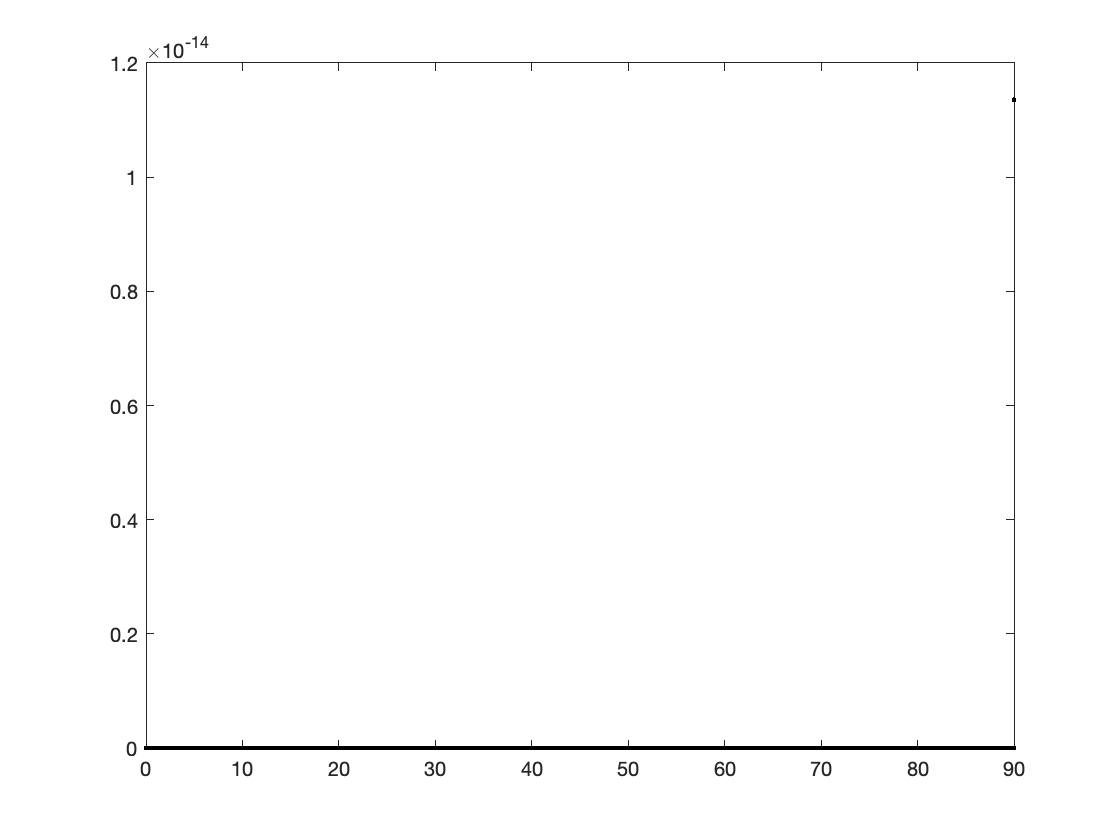


% Step 1: specify initial guess

% Step 2 L Iterate until xn -> xn+1;

% Step 3L xn + 1 from xn

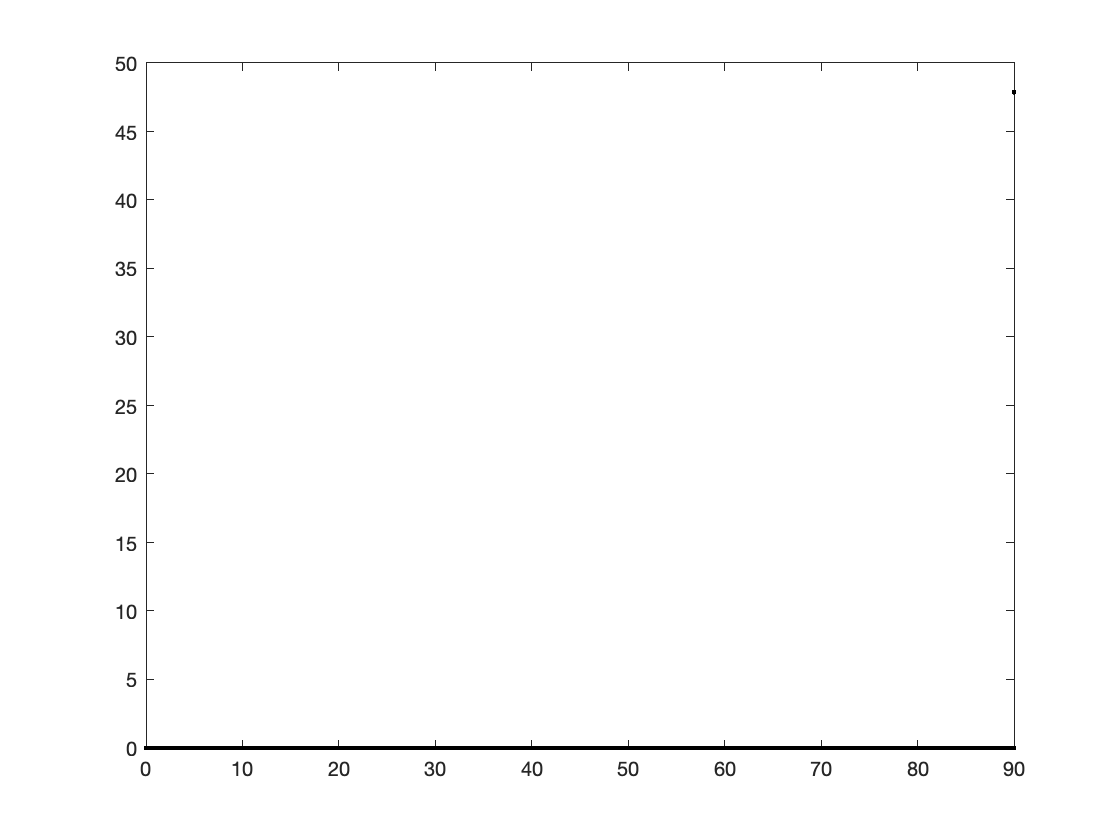

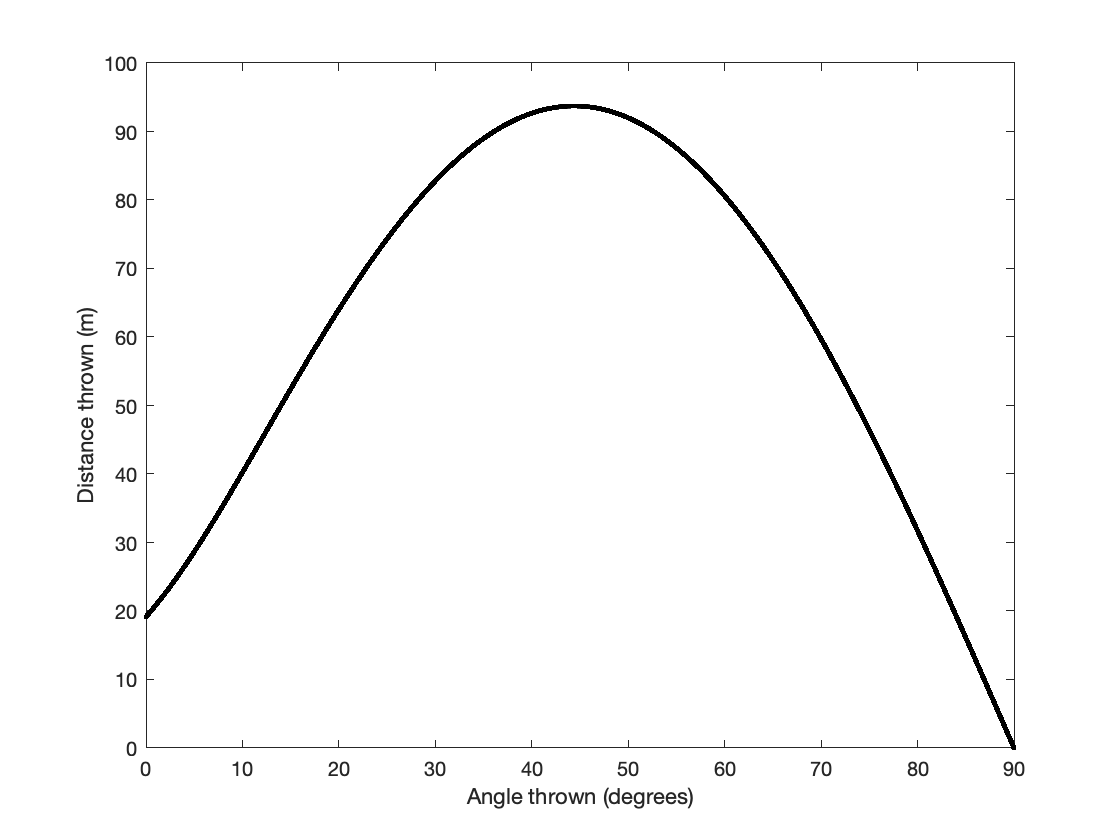

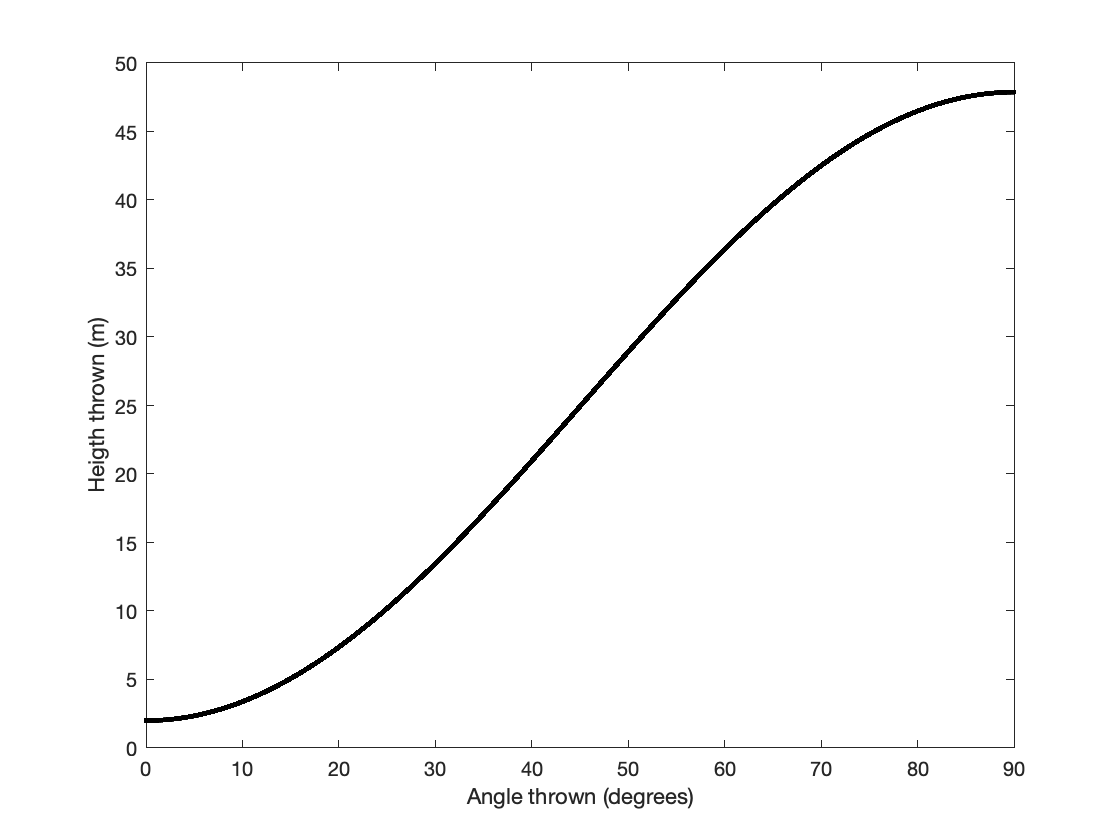


% Step 4: compare xn and xn+1 to determine if loop should continue
